# `MATLAB基础教程`

`作者：To_Fourier`

`创建时间：2020年7月26日20：57`

`修改时间：2020年7月28日8：47`

`个人博客：`[`https://qiuming.blog.csdn.net/`](https://qiuming.blog.csdn.net/)

`GitHub：`[`https://github.com/QiuMingZS`](https://github.com/QiuMingZS)

# `MATLAB概述`

`1.命名：`

`MATLAB = MATrix + LABoratory`

`2.运行平台：`

`Windows, Linux, MacOS`

`3.特点：`

`    1）强大的数值运算功能；`

`    2）强大的图形处理能力；`

`    3）高级但简单的编程环境；`

`    4）丰富的工具箱`

`4.视窗可视化环境`

`    * 标题栏（Title Bar）`

`    * 菜单（Menu）`

`    * 工具栏（ToolBar）`

`    * 视图一：current directory/workspace`

`    * 视图二：command window `

`    * 视图三：command history`

# `Command Window`

`1.命令提示符 >>`

`2.上下左右箭头, Home, End, Delete, Insert`

`3.清空命令行窗口`

clc

`4.清空工作区`

clear

`5.查看帮助`

help sin

`6.查找`

% lookfor sin

`7.查看相关文档`

doc sin

`8.分号取消输出`

a = 5;

`9.续行符`

b = 1 + 2 + 3 + ...
    5 + 6

`10.命令之间的逗号`

c = 5, d = 6

`11.查看MATLAB搜索路径`

path

`12.CTRL + C强制终止`

`13.退出MATLAB`

% exit
% quit
% 直接关闭

# `一个简单的例子`

`要求：`

`编写函数文件arith_1.m，任意输入一个正整数，如果是1，直接输出1。`

`否则：如果是偶数，用2除，如果是奇数，用3乘再加1，反复这个过程，直到所得到的数为1，将依次得到的这个数列返回（数列中包括输入的正整数）`

`代码示例：`

arith_1(65)

# `MATLAB的工作空间`

`  * 当MATLAB启动后，系统会自动建立一个工作空间，这时的工作空间内只包含系统所提供的一些特殊变量，如pi，eps，nan，i等。`

`  * 随着用户的使用，逐渐增加一些用户自己定义的变量。`

`  * 使用who，whos可以查看到当前工作空间所有变量的情况。`

`  * 使用clear可以删除全部或部分工作空间中的变量。`

`  * 关闭MATLAB，释放工作空间，所有变量会被释放。`

# `MATLAB的搜索路径`

path

`MATLAB遇到一个命令（test）时，其处置过程为： `

`    1.将test视为使用者自定义的变量。 `

`    2.若test不是使用者自定义的变量，将其视为系统定义的常量。 `

`    3.若test不是常量，检查其是否为当前工作目录下的M文件。 `

`    4.若不是，则由搜寻路径寻找是否有test.m的文件。 `

`    5.若在搜寻路径中找不到，则MATLAB会印出错误讯息。`

`    * 处置过程可能因版本不同而略有不同。  `

# `变量`

`MATLAB特殊之处(相较于C语言)：无需进行变量声明。`

`* 遇到新变量名时，自动生成变量，并指定合适的存储空间。`

`* 如变量早已存在，则自动更新。`

## `1.系统特殊变量 `

% ans
1 + 2 + 3 + 4 + 5

% 其他的系统特殊变量
pi
inf
eps
nan
NaN
i
j

## `2.变量命名规则`

`* 变量名由字母、数字和下划线组成。`

`* 字母间不可留空格且第一个字符必须为字母`

`* 区分大小写。`

`* 变量名的长度上限为n个字符。`

`* 变量名不能为中文；`

`* 系统变量名不要和自定义重名。`

`万一自定义变量名和系统变量名一样结果会怎样？怎么办?`

isvarname  myVarName  
isvarname  7myVarName

## `3.获取当前变量`

`命令行直接键入变量名。`

a = 5;
a

## `4.变量的精度`

`控制显示精度函数： format`

`控制精度计算的函数：`

`    digits(n):设置缺省的精度；`

`    vpa(S,n):将S表示为n位有效位数的形式。`

x = 0;
for n = 1:82
    x = x + 0.01;
end
x == 0.82  

ans = logical
   0


format long
x

x =    0.820000000000001


   
x=0;
for n = 1:82
    x = x + 1;
end
x == 82

ans = logical
   1


## `5.查看变量`

`who：查看当前工作区（workspace）的变量。`

`whos：查看当前变量的详细信息。`

## `6.清除变量`

`clear：清除所有定义过的变量。`

`clear 变量名：清除某个变量。`

## `7.变量的初始化（三种方式）`

`* 用赋值语句初始化变量。`

`* 用input函数从键盘输入初始化变量。`

in1 = input('enter data:');
in2 = input('enter data:', 's')
in1+in2

`* 从文件读取一个数据。`

## `8.变量的作用域`

`（1）局部变量（Local）：在函数中使用的变量，`

`    只能在函数的范围内使用。`

`（2）全局变量（Global）：在命令文件或工作空间中定义。`

`    用global定义全局变量。`

global  Gvar1 Gvar2 Gvar3

`（3）永久变量（Persistent）：只能在函数文件中定义和使用，只允许定义它的函数存取。只有清除函数或者关闭MATLAB时，才能从内存中清除它们。`

% persistent perVar

`TIPS：尽量不使用全局变量和永久变量！`

# `数据的读写`

`思考：`

`    关闭MATLAB，释放工作空间，所有变量会被释放。`

`    这样会出现什么问题？`

`解决办法：`

`    将工作空间中的变量存储到文件中。`

`    这样，即使退出了MATLAB系统，变量依然存在。需要使用时，将这些变量从文件中读取出来即可`

## `1.save命令`

`功能``：将变量以二进制的方式存储至后缀名为.mat的文档中。`

`格式``：save filename`

`注意事项：`

`1) 存储文件为.mat的二进制mat文档中。`

`2) 若文件名缺省，则自动存储到matlab.mat中。`

`3) 若为save filename x 则只将变量x存储到文件中去。`

`4 ) 若为save filename u w –append 则将变量u，w添加到文件名为filename.mat的文件中。`

`5 ) 若为save filename u w –ascii 则将变量u，w保存为filename的8位ASCII文档。`

`6) 若为save filename u w –ascii -double则将变量u，w保存为filename的16位ASCII文档。`

`Note：ASCII文档特色（使用-ascii后缀）：`

`（1）ASCII文档可以看到文档内容。`

`（2）默认的存储格式是二进制的mat文件。存储ASCII文档必须加-ascii。`

`（3）save  -ascii通常只存为一个变量，原有变量名消失。load载入时，取用文件名为变量名。`

`（4）对于复数，save -ascii后只存实部，虚部抛弃。`

`（5）ASCII文件通常比二进制文件大,二进制文档较小，读取速度快。`

`建议：`

`   尽量使用二进制文件存储MATLAB变量。`

## `2.load命令`

`功能``：读取保存在文件中的变量。`

`格式``：load filename`

`      load filename –ascii`

`      load filename –mat`

`注意事项``：`

`    首先，MATLAB在系统默认路径中自动寻找名称为filename.mat的二进制文件。`

`    其次，若无该文件，则找filename的文件，用ASCII方式载入。`

# `MATLAB的三种控制结构`

`   按照程序设计的观点, 任何算法功能都可以通过`

`程序模块组成的三种基本程序结构的组合来实现:`

`* 顺序结构：程序按程序语句或模块在执行流中的 顺序逐个执行。 `

`* 选择结构：程序按设定的条件实现程序执行流的多路分支。 `

`* 循环结构：程序按给定的条件重复地执行指定的程序段或模块。`

## `1.顺序结构`

a = 0:0.01:2*pi

a =                    0   0.010000000000000   0.020000000000000   0.030000000000000   0.040000000000000   0.050000000000000   0.060000000000000   0.070000000000000   0.080000000000000   0.090000000000000   0.100000000000000   0.110000000000000   0.120000000000000   0.130000000000000   0.140000000000000   0.150000000000000   0.160000000000000   0.170000000000000   0.180000000000000   0.190000000000000   0.200000000000000   0.210000000000000   0.220000000000000   0.230000000000000   0.240000000000000   0.250000000000000   0.260000000000000   0.270000000000000   0.280000000000000   0.290000000000000   0.300000000000000   0.310000000000000   0.320000000000000   0.330000000000000   0.340000000000000   0.350000000000000   0.360000000000000   0.370000000000000   0.380000000000000   0.390000000000000   0.400000000000000   0.410000000000000   0.420000000000000   0.430000000000000   0.440000000000000   0.450000000000000   0.460000000000000   0.470000000000000   0.480000000000000   0.49000000000

sin_a = sin(a)

sin_a =                    0   0.009999833334167   0.019998666693333   0.029995500202496   0.039989334186634   0.049979169270678   0.059964006479445   0.069942847337533   0.079914693969173   0.089878549198011   0.099833416646828   0.109778300837175   0.119712207288919   0.129634142619695   0.139543114644236   0.149438132473599   0.159318206614246   0.169182349066996   0.179029573425824   0.188858894976501   0.198669330795061   0.208459899846100   0.218229623080869   0.227977523535188   0.237702626427135   0.247403959254523   0.257080551892155   0.266731436688831   0.276355648564114   0.285952225104836   0.295520206661340   0.305058636443443   0.314566560616118   0.324043028394868   0.333487092140814   0.342897807455451   0.352274233275090   0.361615431964962   0.370920469412983   0.380188415123161   0.389418342308651   0.398609327984423   0.407760453059570   0.416870802429211   0.425939465066000   0.434965534111230   0.443948106965520   0.452886285379068   0.461779175541483   0.4706258

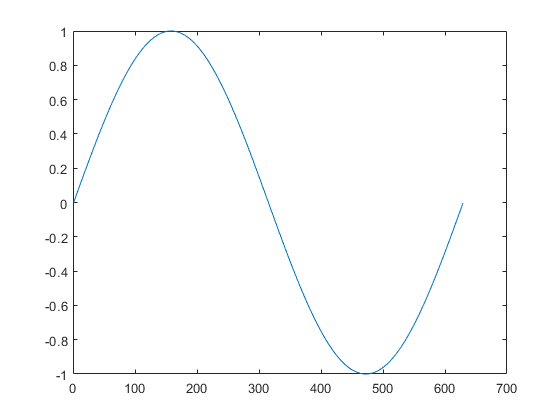

plot(sin_a)

## `2.选择结构`

`* if语句`

clear
n = input('输入n= '); 			
if n >= 90
    r = 'A'
elseif n >= 80
    r = 'B'
elseif n >= 70
    r = 'C'
elseif n >= 60
    r = 'D'
else
    r = 'E'
end

r = 'E'

`* switch语句`

clear
n = input('输入n= '); 
lowline = floor(n/10) 
switch lowline
    case {10, 9}
        r = 'A'
    case 8
        r = 'B'
    case 7
        r = 'C'
    case 6
        r = 'D'
    otherwise
        r = 'E'
end

## `3.循环结构`

`* for语句`

clear
sum = 0;
for i = 1:1:100
    sum = sum + i;
end
sum

sum =         5050


`* while语句`

clear
sum = 0; 
i = 0;
while i < 100
    i = i + 1;
    sum = sum + i;
end
sum

## `4.break和continue语句`

`* break语句用于立即跳出含该break语句的循环语句。`

`* continue语句用于提前结束当前循环。`

for ii = 1:5
    if ii == 3
        break
    end
    fprintf('ii = %d \n', ii)
end

ii = 1 
ii = 2 


disp('End of loop!')

End of loop!


for ii = 1:5
    if ii == 3
        continue
    end
    fprintf('ii = %d \n', ii)
end

ii = 1 
ii = 2 
ii = 4 
ii = 5 


disp('End of loop!')

End of loop!


## `5.return语句`

`    用于终止当前命令的执行, 在任何地方遇到return时程序立即终止。`

## `6.try-catch语句`

`* 用于实现异常处理机制。`

`* 需要检测的程序必须放在try语句块中执行。`

`* 异常由catch语句捕获并处理。`

clear
N = input('please input N=')

N =      4


A = magic(3)

A =      8     1     6
     3     5     7
     4     9     2


try
    A_N=A(N,N)
catch 
    fprintf('You Number is too big!')
    A_end=A(end,end)
end

You Number is too big!

A_end =      2


# `M文件的定义、调用和调试`

`主要类型：`

`* 命令文件（脚本文件）`

`* 函数文件`

`编程原则：`

`* 百分号 % 后面的内容是程序的注释信息。`

`* clear命令用于清除变量，通常用于主程序开头。`

`* 充分利用MATLAB提供的函数来进行运算。`

`* 在语句后输入分号，使中间结果不显示在屏幕上。`

`* 输入少量数据时，可以使用input命令；`

`* 大量的数据输入最好通过子程序完成，在主程序中只需要调用该子程序即可。`

`* 尽量采用主程序调用子程序的方法，使主程序清晰易读，便于维护。`

`* 充分利用调试功能对程序进行调试，有的时候隐含的逻辑错误更不容易发现，危害却更大。`

`* 设置MATLAB的工作路径和当前工作目录，方便操作和运行程序。`

## `1.命令文件（脚本文件）`

`* MATLAB代码按顺序组成的命令序列。`

`* 不接受输入参数和输出参数。`

`* 与MATLAB工作空间共享变量空间。`

## `2.命令文件的调用方法`

`* 在MATLAB命令窗口直接输入命令文件的文件名即可。 `

## `3.Tips:`

`* 命令文件最好保存在当前目录下。 `

`* 命令文件的文件名不要与其他函数/文件重名。 `

`* 命令文件的文件名不要与变量重名。 `

## `4.函数文件`

`* 定义一个函数，需要制定输入参数和输出参数。`

`* 函数文件具有独立的内部变量空间。 `

## `5.函数文件的调用`

`* 输入函数文件的文件名并代入指定的实际参数即可。`

`* MATLAB支持函数的嵌套调用和递归调用。`

## `6.函数文件的格式`

`* 输出参数多于一个时，应使用中括号； `

`* 输入参数多于一个时用逗号隔开； `

`* 函数名与所存的m文件名应同名； `

`* 函数体中可使用错误提示信息：warning（‘message’）。 `

## `7.函数文件与命令文件的区别    `

`* 函数文件用function关键字定义，命令文件则不用；`

`* 函数文件可以传递参数，而命令文件不能传递参数；`

`* 函数文件中定义和使用的是局部变量，只在函数内有效。`

`* 命令文件中的变量都是全局变量，退出命令文件后仍然有效。 `

## `8.函数文件与命令文件的创建   `

`命令文件的创建基本步骤如下：`

`* 打开MATLAB的M文件编辑器或任何一个文本编辑器；`

`* 写入MATLAB的命令代码；`

`* 保存文件名为filename.m即完成了命令文件的创建。`

`函数文件的创建基本步骤如下：`

`* 打开MATLAB的M文件编辑器或任何一个文本编辑器；`

`* 写入MATLAB的代码，注意第一行必须用function关键字，并定义函数四要素；`

`* 保存文件名为funcname.m，即完成了命令文件的创建。`

`注意，文件名与函数名应同名，最好将M文件放置在MATLAB搜索路径下。`

# `函数基础`

`MATLAB常用的基本数学函数` 

`abs(x)：     纯量的绝对值或向量的长度 `

`sqrt(x)：    开平方 `

`real(z)：    复数z的实部 `

`imag(z)：    复数z的虚部 `

`conj(z)：    复数z的共轭复数 `

`angle(z)：   复数z的相角`

`round(x)：   四舍五入至最近整数 `

`fix(x)：     无论正负，舍去小数至最近整数 `

`floor(x)：   地板函数，即舍去正小数至最近整数 `

`ceil(x)：    天花板函数，即加入正小数至最近整数 `

`rat(x)：     将实数x化为多项分数展开`

`rats(x)：    将实数x化为分数表示 `

`sign(x)：    符号函数 (Signum function)。 `

`rem(x,y)：   求x除以y的馀数 `

`gcd(x,y)：   整数x和y的最大公因数 `

`lcm(x,y)：   整数x和y的最小公倍数 `

`exp(x)：     自然指数 `

`pow2(x)：    2的指数 `

`log(x)：     以e为底的对数，即自然对数 `

`log2(x)：    以2为底的对数 log10(x)：以10为底的对数 `

## `1.匿名函数`

`通常只由一句很简单的声明语句组成。`

`* 匿名函数也可以接受多个输入和输出函数。`

`* 匿名函数的优点是不需要维护一个函数文件。`

`【调用格式】`

`fhandle = @(arglist)expr`

`例题：创建匿名函数myfuncHandle,输入参数为`$x$`，函数完成计算`$x^2 +2x+1$`。`

myfuncHandle  = @(x)(x^2+2*x+1)
myfuncHandle(10)

## `2.主函数和子函数`

`在一个单个的M文件中我们可以定义多个函数。如果多个函数出现在一个文件中，那么第一个定义的（最好与M文件同名的）函数为主函数，其下面定义的的函数称为子函数。`

` 注意：子函数只能被同一文件中的函数调用。`

out1 = mainFunc(5)

## `3.私有函数`

`指存放在private子目录中的函数。`

`注意``： 私有函数只能由其父目录中的函数调用；在函数调用时优先于其他路径上的函数。`

`调用次序： 子函数 -> 私有函数 -> 搜索路径中的函数。`

## `4.函数的调用`

`函数调用顺序：`

`*  变量`

`*  子函数`

`*  私有函数`

`*  当前目录里的函数`

`*  搜索其他路径`

`调用语法：`

`* funcname 参数1 参数2 … 参数n`

`* funcname(参数1 参数2 … 参数n)`

sin(5)

`* output = funcname(参数1，参数2，…,参数n)`

`* [out1,out2,…,outn] = funcname(参数1，参数2，…,参数n)`

## `5.函数的参数传递`

`* 按值传递机制：当一个函数调用发生时，MATLAB 将会复制实参生成一个副本，然后把它们传递给函数。这次复制是非常重要的，因为它意味着虽然函数修改了输入参数，但它并没有影响到调用者的原值。`

`* 防止了因函数修改变量而导致的严重错误。`

a = 2; 
b = 6;
fprintf('Before sample: a = %f, b = %f\n', a, b);
out = sample(a, b);
fprintf('After sample: a = %f, b = %f\n',a,b);
fprintf('After sample: out = %f \n', out);

## `6.函数的参数可调性`

`* MATLAB在函数调用上有一个特色，函数所传递参数数目的可调性，即`

`  传递的参数的个数可以任意。`

`MATLAB提供了两对永久变量：`

`* nargin和varargin：用于检查被调用函数的输入参数数目,检查函数体内的被调用时的输入参数的值。`

`* nargout和varargout：用于检查被调用函数的输出参数的个数和每个输出参数`

area = circle(5, 'b')
circle(5)
circle(5, 'r')

## `7.程序设计的基本步骤`

`（1）清晰地陈述你要解决的问题`

`（2）确定程序的输入输出`

`（3）为你的程序设计算法`

`（4）将算法转化为程序语言`

`（5）调试程序`

# `矩阵`

## `1.矩阵是什么？`

`(1)矩阵是线性代数的基本运算单元。`

`(2)矩阵含有M行N列数值。`

`(3)矩阵中的元素可以是实数或复数。`

`(4)矩阵相关的基本运算：加，减，内积，`

`* 矩阵的分类`

`（1）数值矩阵（实数和复数）`

`（2）符号矩阵`

`（3）特殊矩阵`

## `2.矩阵的构造`

`（1）实数数值矩阵的构造`

`方法一：由命令窗口直接输入。`

`    输入规则：`

`        同一行中不同元素用逗号或者空格符来分隔；`

`        空格个数不限；`

`        不同行用分号分隔或者分行输入；`

`        所有元素置于一对方括号之内；`

`        数据元素可以是表达式，MATLAB自动计算结果。`

`    例:输入矩阵A，B的值。`

A=[1, 2, 3, 4;
   5, 6, 7, 8;
   9, 10,11,12;
   13,14,15,16]
B=[1,sqrt(25),9,13
    2 6 10 7*2 
    3+sin(pi),7,11,15
    4, abs(-8),12,16]

`方法二：由m文件生成，`

`    规则：`

`        具体定义矩阵的规则见方法一。 `

`        m文件中的变量名称与文件名不能相同。`

`        否则会出现变量名与文件名的混乱。`

`    例题：由m文件输入矩阵的值。`

A=[1 2 3 4;5,6,7,8
    9,10,11,12;13 14 15 16]
B=[1,sqrt(25),9,13
    2 6 10 7*2 
    3+sin(pi),7,11,15
    4, abs(-8),12,16]

`方法三：由文本文件生成，`

`    规则：`

`        建立txt文件，直接用load调用此文件。`

`        txt文件中不含变量名称，文件名即为矩阵变量名。`

`        每行数值个数必须相等。`

`    例题：由文本文件输入矩阵的值。`

load matrix_txt.txt

`如何从excel中读取所需要的数据？`

`* excel读取函数xlsread`

`* dat  读取函数csvread`

`（2）复数数值矩阵的构造`

`构造方法同实数数值矩阵；将若干元素换成复数即可。`

A=[1 2 3 4;5,6,7,8; 1+2i,3+4i,2-8i,9-7i]

`（3）符号矩阵的构造`

`构造方法同实数数值矩阵；将若干元素换成符号即可。`

syms x y z;
A=[x 2 3 4;5,y,7,8; 9 10 11 z]

`（4）特殊矩阵的构造`

a = magic(3)

## `3.矩阵的修改`

`（1）部分扩充`

`    调用格式：D=[A;B C]`

`        A为原矩阵，B、C中包含要扩充的元素，D为扩充后的矩阵。`

`    例如： 扩充一个矩阵`

A = magic(3)
D = [A;A]
% D = [A;A A]
D = [A;A;A]

`（2）部分删除`

`   调用格式：A(:,n)=[]`

`            A(m,:)=[]`

`        A(:,n)=[]表示删除矩阵A的第n列；`

`        A(m,:)=[]表示删除矩阵A的第m行。`

`    例如：删除矩阵A的第二列和第三行。`

A = magic(3)
A(:,2)=[]
A(3,:)=[]

`（3）部分修改`

`    调用格式： A(m,n)=a；`

`              A(m,:)=[a]；`

`              A(:,n)=[b]；`

`        A(m,n)=a表示修改矩阵A的第（m，n）元素为a；`

`        A(m,:)=[a]表示修改矩阵A的第m行元素为a;`

`        A(:,n)=[b]表示修改矩阵A中第n列的元素为b。`

`例如：修改矩阵A的第二列元素和第三行元素。`

clear
A = magic(3)
A(:,2)=[1]
A(3,:)=[2]
A(1, 1) = 5

`（4）结构改变—左右翻转`

`    函数命令：fliplr`

`    调用格式：fliplr（A）`

`        fliplr（A）表示矩阵A行数不变，其元素左右翻转。`

`    例如：左右翻转矩阵A元素。`

A = magic(3)
fliplr(A)

`（5）结构改变—上下翻转`

`    函数命令：flipud`

`    调用格式：flipud（A）`

`        flipud（A）表示矩阵A行数不变，其元素上下翻转。`

`    例如：上下翻转矩阵A元素。`

flipud(A)

`（6）结构改变—逆时针旋转`

`    函数命令： rot90`

`    调用格式： rot90（A）`

`              rot90（A，k）`

`        rot90（A,k）表示矩阵A元素逆时针翻转k个90度。`

`    例如：逆时针旋转矩阵A元素。`

rot90(A,2)
rot90(A,-2)

`（7）结构改变—按指定维数翻转矩阵`

`    函数命令：flipdim`

`    调用格式：flipdim(A，dim)`

`        flipdim(A,1)=flipud(A)`

`        flipdim(A,2)=fliplr(A)`

`（8）结构改变—平铺矩阵`

`    函数命令：repmat`

`    调用格式：repmat(A,m,n)`

`             repmat(A,[m,n])`

repmat(magic(3),2,1)

`    提问：repmat(A,m,n)中A是一个数a时，表示什么？`

## `4.矩阵的变维`

`（1）：`

`    调用格式：B(:)=A(:)`

`    提问：B=A(:)表示什么？`

`        表示将矩阵A中的所有元素按列顺序合并成为一个向量。`

clear
A=[1 2 5 4; 6 7 0 1]
B=ones(4,2)
B(:)=A(:)

`    讨论几个问题：`

`        1.对B矩阵的维度有何要求？`

`        2.对B矩阵的元素值有何要求？`

`        2.如何变维？`

`（2）reshape`

`    调用格式：B=reshape(A,m,n)`

`        注意：使用reshape时，B中元素个数与A中相同！`

`    例如：已知A=[1:8],用矩阵A元素构成2×4维的矩阵B。`

A=[1:8]
B=reshape(A,2,4)     
B=reshape(A,4,2)

## `5.矩阵的引用`

`引用格式``：`

`arrayName(m,n)；引用二维数组的第m行n列的元素`

`arrayName(m,:)；引用二维数组的第m行的所有列元素`

`arrayName(:,n)；引用二维数组的第n列的所有行元素`

`arrayName(m1:m2,n)；引用二维数组的第n列中m1至m2行的元素`

`arrayName(m,n1:n2)；引用二维数组的第m行中n1至n2列的元素`

`arrayName([m1 m2],n)；引用二维数组的第n列中m1行和m2行的元素`

`arrayName(m,[n1 n2])；引用二维数组的第m行中n1列和n2列的元`

`arrayName([m1 m2],[n1 n2])`

`问题：`

`    如何得到不同行也不同列的散列的若干个数据？`

`把握MATLAB中列序的概念！`

a = magic(3)
b = a([2, 6])

## `6.常用特殊矩阵`

`（1）空矩阵`

`        函数命令：[]`

`        调用格式：B=[]`

`（2）单位矩阵`

`        函数命令：eye`

`        调用格式：B=eye(n): 生成n×n单位阵`

`                 B=eye(m,n)：生成m×n单位阵         `

`                 B``=eye(size(A))：生成与A维度相同的单位阵`

`    例题: 若A=[1,2,3;2,3,4],求B=eye(size(A)) `

A=[1,2,3;2 3 4]  
B=eye(size(A))
B=eye(5,7) 
B=eye(5)         

`（3）全零矩阵`

`        函数命令：zeros`

`        调用格式：B=zeros(n): 生成n×n零矩阵`

`                 B=zeros(m,n)：生成m×n零矩阵`

                 `B``=zeros(size(A))：生成与A维度相同的零矩阵      `

`    例题: 若A=[1,2,3;2,3,4],求B=zeros(size(A)) `

A=[1,2,3;2 3 4]  
B=zeros(size(A))
B=zeros(5,7) 
B=zeros(5)         

`（4）全1矩阵`

`        函数命令：ones`

`        调用格式：B=ones(n): 生成n×n全1矩阵`

`                 B=ones(m,n)：生成m×n全1矩阵`

                 `B``=ones(size(A))：生成与A维度相同的全1矩阵      `

`例题: 若A=[1,2,3;2,3,4],求B=ones(size(A)) `

A=[1,2,3;2 3 4]  
B=ones(size(A))
B=ones(5,7) 
B=ones(5)         

`（5）随机矩阵（0～1）`

`    函数命令：rand`

`    调用格式：B=rand：产生一个随机数 `

`              B=rand(n): 生成n×n随机矩阵`

`              B=rand(m,n)：生成m×n随机矩阵`

              `B``=rand(size(A))：生成与A维度相同的随机矩阵      `

`    例题: 若A=[1,2,3;2,3,4],求B=rand(size(A)) `

A=[1,2,3;2 3 4]  
B=rand(size(A))
B=rand(5,7)    
B=rand(5)         

`    例题: 生成区间[10，15]内均匀分布的3阶随机矩阵。 `

m=10;
n=15;
B=m+(n-m)*rand(3)         

`（6）随机矩阵（0均值单位方差正态分布）`

`    函数命令：randn`

`    调用格式：B=randn：产生一个随机数 `

`              B=randn(n): 生成n×n随机矩阵`

`              B=randn(m,n)：生成m×n随机矩阵`

              `B``=randn(size(A))：生成与A维度相同的随机矩阵      `

A=[1,2,3;2 3 4]  
B=randn(size(A))
B=randn(5,7) 
B=randn(5)         

`    例题: 生成均值为0.5，方差为0.05的3阶矩阵。 `

mu=0.5;
sigma=0.05;  
B=mu+sqrt(sigma)*randn(3)   

`（7）魔方矩阵`

`    函数命令：magic`

`    调用格式：B=magic(n): 生成n×n魔方矩阵`

`          tip：魔方矩阵值行、列、正、反对角线之和相等的矩阵。且n!=2.`

`    例题: 求3阶魔方矩阵 `

B=magic(3)

`（8）稀疏矩阵`

`    函数命令：sparse`

`              full`

`    调用格式：B=sparse(A): 转换A矩阵为稀疏矩阵`

`              B=full(A):  转换A矩阵为完全矩阵      `

`    例题: 将完全矩阵F=[0 0 3;1 0 0;0 5 0]转化成稀疏矩阵S。`

F=[0 0 3;1 0 0;0 5 0]
S=sparse(F)   
F=full(S)  

`Next：这几个函数生成什么矩阵？`

A = magic(3)
diag(A)
triu(A)
tril(A)

## `7.特殊数组`

`（1）字符数组`

`    调用格式：`

`        s=‘string’         `

`        name=[‘str1’ ’str2’ ’str3’]`

s1=['who' 'are' 'you']
s2=['I''m' 'Tin' 'Tin']
s3=[s1 s2]
m=size(s1)
n=size(s2)
k=size(s3)

`字符串转换方式一`

`    函数命令：char`

`    调用格式：S=char(T)`

`     表示将正整数矩阵转换成字符串矩阵S。`

T=[102 67 132 ; 50 95 78]
S=char(T)

`字符串转换方式二`

`    函数命令：int2str, num2str`

`    调用格式：int2str(A)`

`             num2str(A,k)`

`             num2str(A,format)`

`        表示将数或矩阵转换成字符串或字符串矩阵。`

A=[1.2 6.7 3.2 ; 5.5 9.5 7.8];
B1=int2str(A)
B2=num2str(A)
% B1+B2;   

`字符串转换方式三`

`    函数命令：eval，str2num`

`    调用格式：eval(S)`

`             str2num(S)`

`        表示将字符串S转化为数值。`

a=[1 2]; 
w=[1 3];  
x=[1 2];
S= 'a.*sin(w.*x)'
val=eval(S)   
str2num('3.14159e0')
str2num(['1 2';'3 4'])  
ans.*3

`字符串比较`

`    函数命令：strcmp`

`    调用格式：strcmp(str1,str2)`

`        表示将两个字符串进行比较，相等时返回逻辑值为真。`

str1='bad';
str2='bad';
str3='dab';
strcmp(str1,str2)
strcmp(str1,str3)

`（2）结构数组`

`    提问：结构体的概念？`

`        如果让你统计全班同学基本信息，`

`        你的数据怎么组织？`

`    结构数组：`

`        是根据属性名组织起来的不同类型数据的集合。`

`    * 结构数组的引用：`

`       通过数组名和属性名来引用。`

`    函数命令：struct`

`        调用格式：sn=struct(‘filed1’,{},’filed2’,{},…)`

`例题：结构数组student有name和age两个属性。两组数据： `

`（liu，20）；（Wang，21）。并求student（1），student（2），student（2）.name。`

student=struct('name',{'Liu','Wang'},'Age',{'20','21'})
student(1)
student(2)
student(2).name

`    如果想新增加域field怎么办？`

`    如果想给已有的域filed设置新的值怎么办？`

`例：建立学生档案结构体，并计算每个学生的总成绩。`

`    学号（number）：数值型`

`    姓名（name）：字符型`

`    英语考试成绩（English）：数值型`

`    数学考试成绩（Math）：数值型`

`    物理考试成绩（Physics）：数值型`

stud(1).number=input('please input number:');
stud(1).name=input('please input name:','s');
stud(1).math=input('please input math:');
stud(1).physics=input('please input physics:');
stud(1).english=input('please input english:');
stud(1).total=stud(1).math+stud(1).physics+stud(1).english;
stud(1)

n=input('please input n:');
for i=1:n
    stud(i).number=input('please input number:');
    stud(1).name=input('please input name:','s');
    stud(i).math=input('please input math:');
    stud(i).physics=input('please input physics:');
    stud(i).english=input('please input english:');
    stud(i).total=stud(i).math+stud(i).physics+stud(i).english;
end

`几个相关的函数命令：`

`    fieldnames，size，rmfield，getfield， setfield`

stud
fieldnames(stud)  
size(stud)
rmfield(stud,'number') 
stud=setfield(stud,{1,1},'math','100')
str1=getfield(stud,{1,1},'math')

`•结构数组的嵌套`

`例题：建立嵌套的结构数组。`

a=struct('name','Mike','number','1000','score',struct('math','90','english','89','physics','97'));
a
a(1).number
a(1).score

`（3）细胞数组`

`    提问：`

`        普通数组元素之间有什么关联？`

`        结构数组元素之间有什么关联？`

`        其特殊性在哪里？`

`        还有没有更特殊的可能性？`

`    函数命令：cell `

`细胞数组通常用{}创建，数据通过数组下标引用。`

B=cell(5,3);
B(1,1)={[1 4 3; 0 5 8; 7 2 9]};
B(1,2)={'Anne cat'};
B(2,1)={3+7i};
B(2,2)={0:pi/10:pi};
B{3,1}=[3 4 2;9 7 6;8 5 1];
B{3,2}='Anne Smith';
B{4,1}=3+7i;
B{4,2}=-pi:pi/10:pi;
B

`* celldisp和cellplot方法`

B(1,1)={[1 4 3; 0 5 8; 7 2 9]};
B(1,2)={'Anne cat'};
B(2,1)={3+7i};
B(2,2)={0:pi/10:pi};
B
celldisp(B)       
cellplot(B) 

`引用细胞数组元素：`

C=B{1,1}
C=B(1,1)    
D=B{1,1}(2,2)

`细胞数组的更新：`

% B(3,1)='No.1';    % (?)
B{3,2}='No.2'; 
B{3,3}='No.3';
B       
M=B(1:3,1:2)

`细胞数组的删除：`

B(:,3)=[]   
B{2,3}=[] 
B{2,2}(3)=0

`    ？尝试一下B{1}=[]  和B(1)=[] 。`

`细胞数组中reshape的使用：`

A=cell(3,4)
size(A)
B=reshape(A,6,2)
size(B)

`细胞数组和数值数组的转换`

`    例题：将二维细胞数组F转换为三维数值数据。`

F = cell(2,2)
F{1,1}=[1 2;3 4];
F{1,2}=[-1 0; 0 1];
F{2,1}=[7 8;4 1];
F{2,2}=[4i 3+2i;1-8i 5];
for k=1:4
    for i=1:2
        for j=1:2
            NUM(i,j,k)=F{k}(i,j);
        end
    end
end
F
NUM

`（4）结构细胞数组`

`将结构数组放入细胞数组中，可组成结构细胞数组。`

c_str=cell(1,2);
c_str{1}.label='12/2/94; 12/5/94';
c_str{1}.test=[47 52 55 48; 17 22 35 11];
c_str{2}.xdata=[-0.003 0.41 1.98 2.12 17.11];
c_str{2}.ydata=[-3 5 18 0 9];
c_str{2}.zdata=[0.6 0.8 1 2.2 3.4];
c_str{1}(1).test(2,2)
c_str

# `矩阵的运算`

## `1.矩阵的加减运算`

`    运算符：+，-`

`    运算规则：对应元素相加、减。`

`    例题：A=[1 2;3,4],B=[5 6;7 8],`

`         求X1=A+B; X2=A-B; X3=A+3; X4=B-4。`

A=[1,2;3,4]
B=[5 6;7 8] 
X1=A+B
X2=A-B
X3=A+3
X4=B-4

## `2.矩阵的乘法运算`

`    运算符： *：矩阵乘法`

`            .*：矩阵对应元素相乘（数组运算）`

`    例题：A=[1 2 3; 4,5,6],B=[5 6;7 8;9 10]`

`        求X1=A*B; X2=A*2; X3=A.*B; X4=A.*2。`

A=[1,2,3; 4 5 6]
B=[5 6;7 8;9 10]
X1=A*B;X1=B*A;
X2=2*A
% X3=A.*B  
X4=A.*2

`例题：A=[1 2 3; -2 0 0;1 0 1;-1 2 -3],B=[-1 3;-2 2;2  1],求A*B`

A=[1 2 3; -2 0 0;1 0 1;-1 2 -3],B=[-1 3;-2 2;2  1]
A*B
% B*A 

## `3. 矩阵的除法运算`

`运算符：     `

`    \   ：矩阵左除`

`    /   : 矩阵右除`

`    ./  ：矩阵点右除（数组运算）`

`    .\  ：矩阵点左除（数组运算）`

`提示：     `

`* x=A\B是方程A*x=B的解;`

`* x=B/A是方程x*A=B的解。`

`* 若A为非奇异矩阵，则A\B和B/A可如下获得：`

`        A\B=inv(A)*B         B/A=B*inv(A)`

`例题：A=[1 0 3; 4 13 6;7 4 9],B=[4;7;1]`

`           求X1=A\B；X2=B/A；X3=A./B`

A=[1 0 3; 4 13 6;7 4 9],B=[4;7;1]
X1=A\B
% X2=B/A
X3=A./B
X4=A./2

`例如：哥哥弟弟年龄问题。`

`    哥哥比弟弟大19岁，哥哥年龄是弟弟的3倍还多1，问：哥哥和弟弟的年龄分别是多少？`

`解答方法：`

`    g-3d=1； g-d=19；`

`用矩阵方式解答：`

A=[1,-3;1,-1],B=[1;19]
X1=A\B

## `4.矩阵的乘方运算`

`运算符： `

`    ^: A^p表示矩阵的乘方。`

`    .^: A.^B表示矩阵A的数量乘方。`

`（1）^的运算规则：     `

`A为方阵，p为>0的整数时，A^p表示A自乘p次；p为<0的整数时，A^p表示A-1的|p|次方`

`例题：A=[1 0 3; 4 13 6;7 4 9], 求A^2`

A=[1 0 3; 4 13 6;7 4 9]
A^2      

`（2）.^的运算规则：`

`A.^p 表示矩阵中每个元素的p次乘方。`

`维度相同的A、B矩阵求A.^B，表示矩阵A中元素对矩阵B中的对应元素求幂。结果矩阵与原矩阵维度相同。`

`例题：A=[1 0 3; 4 13 6;7 4 9] ，B=[1,2,3; 4,5,6; 7,8,9]`

`            求X1=A.^2，X2=A.^B`

A=[1 0 3; 4 13 6;7 4 9]
B=[1 2 3; 4 5 6;7 8 9]
X1=A.^2
X2=A.^B

## `5.矩阵的转置`

`运算符：'`

`运算规则：`

`（1）若矩阵A的元素为实数、则A’返回A的转置；`

`（2）若矩阵A为复数矩阵，则A’中的元素由A对应元素的共轭复数构成。`

`例题：A=[1 0 3; 4 13 6;7 4 9]；B=[1 2 3; 4 5 6;7 8 9+9i]`

`            求X1=A’ , X2=B’`

A=[1 0 3; 4 13 6;7 4 9]
B=[1 0 3; 4 13 6;7 4 9+9i]
X1=A'
X2=B'

## `6.矩阵的逆`

`运算符：inv`

`调用格式：B=inv(A)`

`例题： G=[1 2 0; 2 5 -1;4 10 -1], 求G的逆，并验证之。`

G=[1 2 0; 2 5 -1;4 10 -1]
X=inv(G)
DW1=G*X
DW2=X*G

## `7.矩阵的特征值`

`运算符：eig`

`调用格式：eig(A)`

`例题：求矩阵A的特征值。其中A=[1 0 0;0 2 0;0 0 3]。`

A=[1 0 0;0 2 0; 0 0 3]
eig(A)

## `8.求矩阵的特征多项式`

`运算符：poly`

`调用格式：poly(A)`

`例题：求矩阵A的特征多项式。其中A=[1 2 0;2 5 -1;4 10 -1]。`

A=[1 2 0;2 5 -1;4 10 -1] 
poly(A)

## `9.求矩阵的秩`

`运算符： rank`

`调用格式：rank(A)`

`例题：求矩阵A的秩。其中A=[1 2 3;4 5 6]。`

A=[1 2 3;4 5 6] 
rank(A)

## `10.求矩阵元素的个数`

`运算符：numel`

`调用格式：numel(A)`

`例题：求矩阵A的个数。其中A=[1 2 3;4 5 6]。`

A=[1 2 3;4 5 6] 
numel(A)

## `11.方阵的行列式`

`运算符：det`

`调用格式：det(A)`

`例题：求方阵A的行列式的值。其中A=[1 1 0; 0 0 2； 0 5 -1]。`

A=[1 1 0; 0 0 2;0 5 -1]
det(A)

## `12 方阵的迹`

`运算符：trace`

`调用格式：trace(A)`

`例题：求方阵A迹。其中A=[1 1 0; 0 0 2； 0 5 -1]。`

A=[1 1 0; 0 0 2;0 5 -1]
trace(A)

# `矩阵的关系运算和逻辑运算`

## `1.关系运算符`

`    ==，~=，>, >=, <,  <=`

`    主要用来对矩阵与数，矩阵与矩阵进行比较，返回二者关系的，由数0和数1组成的矩阵，0和1分别表示不满足和满足指定关系。`

A=[1 2;2 3]
B=A==1
B=A==2
B=A==3
C=[2 2; 2 2]
B=C==A

## `2.逻辑运算符`

`    & , | , ~,  xor`

`    MATLAB中，所有非零数值均被认为真，零为假。在判断结果中，判断为真输出1，判断为假输出0。`

A=[1 1; 0 1]
b=0;
B=[0 1 ;0 0 ]
C1=A&b
C2=A|b      
C3=xor(A,B)

## `3.逻辑函数`

`    all：判断是否所有元素为非零值；`

`    any：判断是否存在一个元素为非零值；`

`    exist：查看变量或函数是否存在； `

`    find：找出向量或矩阵中非零元素的位置标识；`

`    isempty：判断矩阵是否为空矩阵；`

`    isequal: 判断几个对象是否相等；`

`    isnumeric:判断对象是否为数值型。`

a=[1 3 5]
A=[1 2 3 ; 0 4 5 ]
B1=all(a)
B2=all(A)
B2 = all(all(A))
B3=all(A,2)

a=[0 3 0]
A=[1 0 3;0 0 5]
B1=any(a)
B2=any(A)
B3=any(A,2)

a1=exist('work')
a2=exist('filtdes')
a3=exist('c:\windows')

A=[1.2 0 3.5 ; 0 0 5.4]
k=find(A)
[m,n]=find(A)
[m,n,v]=find(A)

A=[0.34 0.6]
B=[0.34 0.6]
C=['who']
isequal(A, B)
isequal(A, C)

A=[0.34 0.6]
B=[1+2i 0.6+3i]
C=['who']
isnumeric(A)
isnumeric(B)
isnumeric(C)

# `多项式`

`    形如`$P\left(x\right)=a_0 x^n +a_1 x^{n-1} +\ldotp \ldotp \ldotp +a_{n-1} x+a_n$`的式子,MATLAB中，多项式用行向量表示：`$P=\left\lbrack a_0 \;a_1 \;\ldotp \ldotp \ldotp a_{n-1} \;a_n \right\rbrack$

## `1.多项式的构造`

`* 直接输入法`

A = [1 3 5 7 9 0 0]

`* 使用poly方法`

`例题：已知向量A=[1 -34 -80 0 0]，P(x)=(x-1)(x+34)(x+80)(x-0)(x-0)`

`用此向量构造一多项式并显示结果。`

A=[1 -34 -80 0 0 ]
poly(A)

`* 使用poly2sym方法`

`例题：已知向量A=[1 -34 -80 0 0]，P(x)=(x-1)(x+34)(x+80)(x-0)(x-0)`

`用此向量构造一多项式并显示结果。`

A=[1 -34 -80 0 0 ]
PA=poly(A)
poly2sym(PA)

## `2.多项式的运算`

`* 多项式的加减运算`

`运算符：+  -`

`注意事项：`

`（1）具有相同的阶次；`

`（2）如果阶次不同，低阶的多项式必须用零填补至高阶多项式的阶次。`

`例题：求两个多项式`$a\left(x\right)=5x^4 +4x^3 +3x^2 +2x+1$`;`$b\left(x\right)=3x^2 +1$`的和。`

a=[5 4 3 2 1]
b=[3 0 1]
% a+b
c=a+[0 0 b]

`* 多项式的乘法运算`

`调用函数：conv(a,b)`

`例题：求两个多项式`$a\left(x\right)=5x^4 +4x^3 +3x^2 +2x+1$`;`$b\left(x\right)=3x^2 +1$`的积。`

a=[5 4 3 2 1]
b=[3 0 1]
c=conv(a,b)

`* 多项式的除法运算`

`调用函数：deconv(a,b)`

`调用格式：[div,rest]=deconv(a,b)`

`    div:  商多项式`

`    rest: 余数多项式`

`例题:求两个多项式`$a\left(x\right)=5x^4 +4x^3 +3x^2 +2x+1$`;`$b\left(x\right)=3x^2 +1$`的商。`

a=[5 4 3 2 1]
b=[3 0 1]
[div,rest]=deconv(a,b)

`* 多项式的微分运算`

`调用函数：polyder`

`调用格式：B=polyder(A)`

`例题：求多项式`$p\left(x\right)=2x^4 -6x^3 +3x^2 +7$`的微分。`

p=[2 -6 3 0 7]
q=polyder(p)

`* 多项式求根`

`调用函数：roots`

`调用格式：X=roots(A)`

`例题：求多项式`$p\left(x\right)=2x^4 -6x^3 +3x^2 +7$`的根。`

p = [2 -6 3 0 7]
X = roots(p)

`* 多项式求值`

`调用函数：polyval ，polyvalm`

`调用格式：B=polyval(A,a )`

`         B=polyvalm(A,M)`

`例题:求多项式`$p\left(x\right)=2x^4 -6x^3 +3x^2 +7$`当`$x=1$`时的值。`

p=[2 -6 3 0 7]
polyval(p, 1)
% B=polyval_mex(p,1)

`例题:求多项式`$p\left(x\right)=2x^4 -6x^3 +3x^2 +7$`当x=[1 2;3 4]时的值。`

p=[2 -6 3 0 7]
M=[1 2;3 4]
B=polyvalm(p,M)

`例题:将表达式`$\left(x-4\right)\left(x+5\right)\left(x^2 -6x+9\right)$`展开为多项式，并求其对应的一元n次方程的根。`

p=conv([1 -4],conv([1 5],[1 -6 9 ]))
px=poly2sym(p)
x=roots(p)

`例题:已知一元四次方程对应的四个根为-5，4，3，3。求这个方程所对应的表达式原型。`

x=[-5 4 3 3]
p=poly(x)
px=poly2sym(p)

# `数值运算和符号运算`

`数值运算在运算前必须先对变量赋值，再参加运算。符号运算不需要对变量赋值就可运算，运算结果以标准的符号形式表达。`

`例子：哥哥弟弟年龄问题。解答方法：`

`    g-3d=1；        `

`    g-d=19；`

clear;
syms g d;
eq1 = g-d == 19
eq2 = g-3*d == 1
[x, y] = solve(eq1, eq2, g, d)

## `1.符号变量定义`

`调用命令：`

`    sym, syms`

`调用格式：`

a=sym('a')
b=sym('b')
c=sym('c')                    
syms x y z
x, y, z

## `2.符号表达式的定义`

`使用已经定义的符号变量组成符号表达式。`

syms x y a b c
f1 = a*x^2+b*x+c

`形如：a*x^2+b*x+c`

`提问：谁是自变量？`

`自变量的确定：`

`    方法一：事先明确指定。`

`    方法二：MATLAB自行默认确定。`

`MATLAB自变量确定原则: `

`（1）x被视为默认的自变量。`

`（2）字母位置最接近x的小写字母；      `

`          （...,u,v,w,x,y,z,...）`

`函数symvar帮助我们获取系统定义的自变量`

`格式：symvar(f), symvar(f,1)`

`例如：`

syms a b c x y i j t
f1 = sin(a*x+b*y)
f2 = a*x^2+b*x+c
f3 = 1/(4+cos(t))
f4 = 4*x/y
f5 = 2*a+b
f6 = 2*i+4*j

symvar(f1)
symvar(f2,1)
symvar(f3,2)

## `3.符号方程的定义`

`符号表达式和符号方程的区别：`

`    符号表达式是由数字、函数和变量组成的代数式；`

`    符号方程是由函数和等号组成的等式。`

`例如： `

syms x
equation = sin(x)+cos(x) == 1

## `4.符号运算`

`1.初等代数运算`

`（1）符号的加减乘除幂次方运算`

`              +  -  *  /  ^`

`例如：`

syms a b c x y z v w
(a*x+b*y-c*z)/2*v*w^2
f1 = 1/(a-b)
f2 = 2*a/(a+b)
f3 = (a+1)*(b-1)*(a-b)

`2.一些常用函数`

[n, d]=numden(f1+f2)
p = 2*x^3+3*x^2+4
sym2poly(p)
x=[2,3,0,4]
poly2sym(x)

`3.符号表达式化简`

`collect     % 合并同类项`

`expand      % 展开多项式`

`horner      % 分解成嵌套形式`

`factor      % 因式分解`

`simplify    % 对表达式化简`

% collect
syms x y
f = x^2*y+y*x-x^2-2*x
collect(f)

collect((exp(x)+x)*(x+2))
collect((x+y)*(x^2+y^2+1), y) 

% expand
syms a
f = a^3-1
expand(f)

expand((x-2)*(x-4))
expand(cos(x+y))
expand(exp((a+b)^2))

% horner
horner(x^3-6*x^2+11*x-6)

% factor
factor(x^3-6*x^2+11*x-6)

% simplify
simplify(x^3-6*x^2+11*x-6)
simplify(sin(x)^2 + cos(x)^2)
simplify(exp(c*log(sqrt(a+b))))
simplify((x^2+5*x+6)/(x+2))

`4.再次扩充认识sym函数`

`功能：定义符号表达式;`

`    或将输入参数转换为对应的符号表示，或设定符号变量类型。`

`格式：sym(‘a’) ; `

`      sym(A);`

`      sym(A, 'real'), sym(A, ‘unreal'),`

`      sym(A，flag)    flag为f，r，e，d`

sym(1/3,'f')    % f float
sym(1/3,'e')    % e exp
sym(1/3,'r')    % r 有理数
sym(1/3,'d')    % d 十进制树

`5.求反函数 finverse`

`功能：求得符号函数的反函数。`

`格式：finverse(f)`

`      finverse(f,v)`

`      f: 符号表达式     v：自变量。`

clear
syms x y
finverse(1/tan(x))
f= x^2+y
finverse(f,y)
finverse(f) 

`6.求复合函数 compose     `

`功能：求符号函数的复合函数。`

`格式：compose(f,g)`

`      compose(f,g,z)`

`      compose(f,g,x,z)`

`      compose(f,g,x,y,z)`

syms x y z t u
f = 1/(1 + x^2)
g = sin(y)
h = x^t
p = exp(-y/u)

compose(f,g)
compose(f,g,t)
compose(h,g,x,z)
compose(h,g,t,z)
compose(h,p,x,y,z)   
compose(h,p,t,u,z)

`演练例题：`

`已知f=1/(1+x^2),g=sin(y),求复合函数 f(g(y)).`

clear;
syms x y
f=1/(1+x^2)
g=sin(y)
h=compose(f,g)

`演练例题：`

`已知 f(sin(x/2))=1+cos(x),求f(cos(x)).并计算x=pi/6时函数的值。`

syms x
t=finverse(sin(x/2))
f=1+cos(t)
g=cos(x)
compose(f,g)
subs(ans,pi/6)

`7.表达式替换 subs`

`功能：表达式替换。`

`格式：subs(s)`

`      subs(s,new)`

`      subs(s,old,new)`

a=5;
c=10;
syms x b
y = a*x^2+b*x+c
subs(y)

syms a b
subs(a+b,a,4)
subs(a+b,4)   
subs(cos(a)+sin(b),{a,b},{sym('alpha'),2})

`8.极限`

`函数：limit`

`调用格式： g=limit(f)`

`           g=limit(f, a)`

`           g=limit（f，x，a）`

`           g=limit（f，x，a，‘left’）`

`           g=limit（f，x，a，‘right’）`

`例题：`

syms x
limit(1/x)
limit(1/x,0)
limit(1/x,x,0)
limit(1/x,x,0,'left')
limit(1/x,x,0,'right')

limit(sin(x)/x) 
limit((x-2)/(x^2-4),2) 
limit((1+2*t/x)^(3*x),x,inf)

syms h x;
limit((sin(x+h)-sin(x))/h,h,0) 

`9.微分`

`函数： diff`

`调用格式： diff(f)`

`          diff(f, t)`

`          diff(f,n)`

`          diff(f,t,n)`

`演练例题：`

`已知`$f\left(x\right)={\textrm{ax}}^2 +\textrm{bx}+c$`求f(x)的微分。`

syms a b c x
f = a*x^2+b*x+c
diff(f)
diff(f,2)
diff(f,a) 
diff(f,a,2) 
diff(diff(f),a)

`10.积分`

`函数： int`

`调用格式： int(f)`

`          int(f, t)`

`          int(f,a,b) (a,b 为数值式)`

`          int(f,t,a,b)`

`          int(f,m,n) (m,n为符号式)`

`演练例题：`

`已知f(x)=ax2 +bx+c,求f(x)的积分。`

syms a b c x
f = a*x^2+b*x+c
int(f,x,0,2)
int(f,a)
int(int(f,a),x)

int(1/(1+x^2)) 
int(x*log(1+x),0,1)
int(4*x*t,x,2,sin(t))

int(x/exp(x^3))

`11.级数`

`函数：symsum,taylor`

`调用格式：symsum(s,v,a,b)`

`         taylor(F,v,n)`

syms k
symsum(1/k,k,1,inf)
symsum(1/(k*(k+1)),k,1,inf)

`演练例题：`

`求sin(x)的10阶展开式。并求x=pi/2处的值。`

syms x
sin_x = taylor(sin(x), x, 10)
subs(sin_x,x,pi/2)

`12.方程求解`

`函数：solve     解符号方程式f`

`调用格式：sovle(f1,f2,…,fn, v1,v2,v3,…,vn)`

clear 
syms a b c x
f=a*x^2+b*x+c
solve(f)
solve(f,a)

`13.微分方程求解`

`函数：dsolve     解微分符号方程式f`

`调用格式：`

`    dsolve(f,cond,v)`

`    dsolve(f1,f2,…,fn,cond1,cond2…,condn,v1,v2…,vn)`

`    dsolve(f1,f2,…,fn)`

`注意事项：`

`- Dy代表dy/dt, D2y代表d2y/dt2 。`

`- 如果没有初始条件，则求微分方程的通解。`

`- 系统默认变量t。`

`例题：`

`求微分方程y’=5的通解。`

`求微分方程y’=x的通解，指定x为自变量。`

`求微分方程y’’=1+y’的通解。`

`求微分方程y’’=1+y’的解，y|t=0=1,dy/dt|t=0=0。`

dsolve('Dy=5')
dsolve('Dy=x','x')
dsolve('D2y=1+Dy')
dsolve('D2y=1+Dy','y(0)=1','Dy(0)=0')

clear
syms y(t) 
eq1 = diff(y, t) == 5
cond = y(0)==0
dsolve(eq1,cond)

# `图形绘制`

`MATLAB中进行图形处理时，通常采用下面的步骤：`

`1.  准备绘图数据；`

`2.  选定绘图窗口与绘图区域；`

`3.  调入绘图函数命令；`

`4.  设置图形格式；`

`5.  输出所绘制的图形。     `

`比如：`

x=0:0.01:2
y=sin(x)
plot(x,y)

x=0:pi/100:2*pi
y=2*exp(-0.5*x).*cos(4*pi*x)
plot(x,y)

## `1.图形窗口`

`图形窗口是个独立的窗口，系统自动将图形绘制在图形窗口上。`

`1.图形窗口的创建与控制`

`* 单个图形窗口的创建`

`函数命令：figure`

`调用格式：h=figure`

`         h=figure(n)`

`           该命令创建单个图形窗口。`

`注意事项：`

`    * 若没有打开图形窗口时执行绘图命令，将自动创建一个图形窗口；`

`    * 若执行绘图命令前已经打开几个图形窗口，则绘图命令把图形输出到当前窗口中、并把这个窗口中原来的图形覆盖；     `

`    *  n为图形窗口的编号。`

h1=figure(1)
h2=figure(2)
h3=figure(3)
x=0:0.01:2;y=sin(x);plot(x,y)
x=0:0.01:2;y=cos(x);plot(x,y)

`相关命令：`

`    get(n)：获得第n个图形窗口的有关属性。`

`    set(n)：设置第n个图形窗口的有关属性。`

`例题：作出函数y=sin(x)在区间[0，10]上的图形。`

clf
x=0:0.01:10;
x=0:0.01:10;
y=sin(x);
h=figure(1);
plot(x,y);
set(1,'name','hello')
set(h,'visible','on'); 
% set(h,'visible','off');
get(h);get(1);

`* 多重子图窗口的创建`

`函数命令：subplot`

`调用格式：h=subplot(m,n,p)`

`    该命令将图形窗口分割为多个子图窗口。`

`注意事项：`

`    * 若执行命令前已经存在某一子图，则该命令将新图形输出到相应子图，并把原来子图覆盖。`

`    *  m为子图行数，n为子图列数。`

`    *  p为子图窗口序号。`

`例题：在同一图形窗口、不同坐标系中分别作出y=sin(x),y=sin(2x),y=sin(3x)和y=sin(4x)在[0，2*pi]的图形。`

a = figure(1)
x=(0:0.01:2)*pi;
y1=sin(x);
y2=sin(2*x);
y3=sin(3*x);
y4=sin(4*x);

a=subplot(2,2,1);plot(x,y1);  
b=subplot(2,2,2);plot(x,y2);
c=subplot(2,2,3);plot(x,y3);
d=subplot(2,2,4);plot(x,y4);       

`相关命令：`

`         get(n)：获得第n个图形窗口的有关属性。`

`         set(n)：设置第n个图形窗口的有关属性。       `

get(1);
get(a);
set(a,'visible','off'); 
set(a,'visible', 'on');
set(1,'visible','off');
set(1,'visible','on');

## `2.基本图形函数`

`函数命令：plot`

`调用格式：plot(x)`

`         plot(x,y)`

`         plot(x,y1,x,y2,…)     `

`    plot是绘制二维图形的最基本函数，针对向量或者矩阵的列来绘制曲线的。`

`    在使用plot函数之前，必须首先定义好曲线上每一点的x及y坐标。 `

`plot(x)    `

`* 当x为一向量时，以x元素的值为纵坐标，x的序号为横坐标值绘制曲线。`

`* 当x为一m×n的实数矩阵时，以x序号为横坐标，按列绘制每列元素值相对于其序号的曲线。最终绘制出n条曲线。        `

clf
x=[1 2 3 4 5 6 ]
plot(x)
x=[1 2 ; 3 4] 
plot(x)
x=[1 2 ; 3 4;5 6]      
plot(x)      

`plot(x,y)`

`* 若x，y为同维向量，则以x元素为横坐标值，y元素为纵坐标值绘制曲线。(常见)`

`* 若x是向量，y是有一维与x元素数量相等的矩阵，则以x为共同横坐标，按列绘制y每列元素值，曲线数为y的另一维的元素数。`

`* 若x，y是同维矩阵，则以x，y对应列元素为横、纵坐标分别绘制曲线。曲线数为矩阵的列数。`

x=[1 2 3 4 ]
y=[7 8 9 0]
plot(x,y)
y=[7 8 9 0; 1 2 3 4 ; 2 2 2 2]
plot(x,y)
x=[1 2 3 4 ; 5 6 7 8  ; 9 1 2 3 ]
y=[7 8 9 0; 1 2 3 4 ; 2 2 2 2]
plot(x,y)

`plot(x,y1,x,y2,…)`

`* 若x，y均为同维向量时，以公共的x元素为横坐标值，以y1，y2，…元素为纵坐标值绘制多条曲线。`

`* x，y1，y2均为矩阵时，情况比较复杂，自己试试吧。`

x=[1 2 3 4 ]
y1=[9 1 2 3 ]
y2=[1 2 3 4 ]    
plot(x,y1,x,y2)

x=0:pi/10:2*pi;
y1=sin(x);
y2=cos(x);
plot(x,y1,'r + -',x,y2,'k * :');

## `3.图形修饰函数`

`例题：给例题中的图形中加入网格和标注。`

x=0:pi/10:2*pi;
y1=sin(x);
y2=cos(x);
plot(x,y1,'r + -',x,y2,'k * :');
grid on;
xlabel('Independent Variable X');
ylabel('Dependent Variable Y1&Y2')
title('Sin and Cos Curve')
text(1.5,0.3,'cos(x)');
text(3,0.3,'sin(x)');
axis([0 2*pi -1.1 1.1]);

## `4.``图形的比较显示`

`问题：用什么方法可以把图形进行比较显示？`

`方法一：用同一x，以及不同y进行绘制；`

`方法二：用hold on（/off）命令；`

`方法三：采用subplot命令。`

x=0:pi/10:2*pi;
y1=sin(x);
y2=cos(x);
y3=x;
y4=log(x);
plot(x,y1,x,y2);
hold on;
plot(x,y3);
plot(x,y4);

## `5.其他二维图形绘制函数`

`1.直方图`

`函数命令：bar   barh`

`调用格式：bar(y),bar(y,width);`

`         bar(x,y) , bar(x,y,width); `

`         bar(~,‘grouped’);`

`         bar(~,‘stack’)`

`（1）bar(y),bar(y,width) ，       `

`     bar(y,width,‘grouped’)  `

`     bar(y,width,‘stacked’)`

`     该命令生成一组直方图，可视化结果为m组，每组n个垂直柱。`

`     （y可以为一组向量，或是m×n矩阵。）`

clf;
y=[1 2 3 4];
bar(y);
y=[1 2 3 4 ; 2 3 4 5; 5 6 7 8];
bar(y);
bar(y,1);
bar(y,0.08);

subplot(3,1,1);bar(y);
subplot(3,1,2);bar(y,'grouped');
subplot(3,1,3);bar(y,0.08,'grouped');

subplot(3,1,1);bar(y);
subplot(3,1,2);bar(y,0.08,'stack');
subplot(3,1,3);bar(y,'stack');

`2.面积图`

`函数命令：area   `

`调用格式：area(x,y)           `

`    该命令绘制（x,y）的面积图。`

`    参考plot(x,y)`

clf
x=0:0.01:2*pi;y=sin(x);
area(x,y)

`3.饼图`

`函数命令：pie   `

`调用格式：pie(x)`

`         pie(x,explode)`

`         pie(...,labels)         `

`例题：某班级考试，90分以上32人，80～89分58人，70～79分27人，60～69分21人，60分以下16人，画出饼图。`

x=[32 58 27 21 16];
pie(x);
explode=[0 0 0 0 1];
pie(x,explode);
explode=[0 0 1 0 1];
pie(x,explode);
pie(x,{'you','liang','zhong','jige','cha'});

`4.其他`

`例题：绘制x=[1 2 3 4 5 6 ]的针状图。`

clf
x=[1 2 3 4 5 6];
stem(x);

`例题：绘制x=[1 2 3 4 5 6 ]，y=[1 2 3 4 5 6],u=[1 2 3 4 5 6],v=[1 2 3 4 5 6]的蓝色和红色向量场图、关于（u，v）的羽状图、罗盘图。`

clf
x=[1 2 3 4 5 6];
y=[1 2 3 4 5 6];
u=[1 2 3 4 5 6];
v=[1 2 3 4 5 6];
subplot(2,2,1);quiver(x,y,u,v);
subplot(2,2,2);quiver(x,y,u,v,'r');
subplot(2,2,3);feather(u,v);        
subplot(2,2,4);compass(u,v);


`例题：绘制50个随机数据分布特征的玫瑰花图与根据峰值函数peaks绘制等值线图，并作出1000个随机数的柱状图。`

clf
theta=10*rand(1,50);
Z=peaks;
x=0:0.01:2*pi;y=sin(x);
t=randn(1000,1);
subplot(3,1,1);rose(theta);
subplot(3,1,2);contour(Z);
subplot(3,1,3);hist(t);

`例题：绘制由bucky函数所产生稀疏邻接矩阵的拓扑图及关于向量t=[1 2 3 4 5 6]的阶梯图，并在[0,4*pi]上绘制y=x*esin(x)的误差条形图与彗星图。`

clf
[A,C]=bucky;
t=[1 2 3 4 5 6];
x=0:0.7:4*pi;y=x.*exp(sin(x));l=0.1*y;
subplot(2,2,1);gplot(A,C);
subplot(2,2,2);stairs(t);
subplot(2,2,3);errorbar(x,y,l);
subplot(2,2,4);comet(x,y);

## `6.不同坐标系中作图`

`1.直角坐标系中绘图`

`    函数命令：plot等绘图函数。`

`2.对数坐标系中绘图`

`    函数命令：loglog，semilogx，semilogy`

`    调用格式：loglog(x,y)`

`              semilogx(x,y)`

`              semilogy(x,y)`

`    重要提示：log10（0）数学上没有意义，但MATLAB并不给出错误提示信息。`

`例题：已知x=[1.2 7.0 3.6 5.0 8.0],y=[4.1 5.2 6.3 9.0 15.0], 分别在双对数坐标系，半对数坐标系（分别取横纵轴为对数）绘制（x，y）对应的图形。  `

clf
x=[1.2 7.0 3.6 5.0 8.0];
y=[4.1 5.2 6.3 9.0 15.0]; 
subplot(1,3,1);loglog(x,y);
subplot(1,3,2);semilogx(x,y);
subplot(1,3,3);semilogy(x,y); 

`3.极坐标系中绘图`

`    函数命令：polar`

`    调用格式：polar(theta，r)`

`    重要提示：可使用命令[x,y]=pol2cart(theta,r)将极坐标系的数据点对（theta,r）转化为直角坐标系的数据点对[x,y],命令plot（x，y）和命令polar(theta,r)的效果相同。`

`例题：分别在极坐标系和直角坐标系中作出三叶玫瑰线r=a*cos(3*theta)的图形，这里a=2。`

clf
a=2;
theta=(0:0.01:4)*pi;
r=a*cos(3*theta);
subplot(1,2,1);polar(theta,r);
[x,y]=pol2cart(theta,r);
subplot(1,2,2);plot(x,y);
axis equal;

`4.双轴图`

`    函数命令：plotyy`

`    调用格式：`

` [haxes,hline1,hline2]=plotyy(x1,y1,x2,y2,m1,m2)`

`例题：分别作出z1=A*e-at与z2=sin(bt)的双轴图，这里t在[0,900],A=1000,a=b=0.005。`

clf
t=0:900;A=1000;a=0.005;b=0.005;
z1=A*exp(-a*t);
z2=sin(b*t);
[haxes,hline,hline2]=plotyy(t,z1,t,z2,'semilogy','plot');    

`例如：绘制双轴图`

`    x=0:0.01:2*pi;y1=sin(x);y2=cos(x);`

`    将其左、右坐标轴AX（1）和AX（2）标题分别设置为“正弦函数”和“余弦函数”；`

`    将两根曲线H1和H2的颜色分别设置为红色和蓝色；`

`    设置图例。`

x=0:0.01:2*pi;y1=sin(x);y2=cos(x);
[AX,H1,H2]=plotyy(x,y1,x,y2,'plot');
set(get(AX(1),'Ylabel'),'string','正弦函数');
set(get(AX(2),'Ylabel'),'string','余弦函数');
set(H1,'Color','r');
set(H2,'Color','b');
legend('正弦函数','余弦函数')
% legend off
plot(x,y1,x,y2)
legend('正弦函数','余弦函数')
% legend off

## `7.符号表达式绘图`

`    函数命令：fplot，ezplot`

`    调用格式：`

`    fplot（fun，lims，tol，n，p1,p2,…）    ezplot（fun,lims,fig）`

`    fun: 绘制函数fun的图形；`

`    lims：作图区间；`

`    tol： 相对误差，默认为2e-3；`

`    n：   作图点数，默认值n=1；`

`    p1,p2,…: 函数的参数，默认没有参数。`

`例题：使用命令fplot作出函数y=sin（x）的图形，自变量区间分别为：x在[0,2*pi]之间；x在[pi,3*pi]；x在[-pi,pi],y在[-pi,pi]；x在[0 2*pi]（此时要求作图误差小于0.001）。`

clf
subplot(2,2,1),fplot(@(x)sin(x),[0 2*pi]);
subplot(2,2,2),fplot(@(x)sin(x),[pi 3*pi]);
subplot(2,2,3),fplot(@(x)sin(x),[-pi pi]);
subplot(2,2,4),fplot(@(x)sin(x),[0 2*pi]);

`ezplot（fun，lims，fig）`

`    fun: 绘制函数fun的图形；`

`    lims：作图区间；`

`    fig：图形窗口句柄。`

`    重要提示：ezplot可作隐函数与多元函数的图形。默认作图区间为[-2*pi 2*pi].`

`例题：绘制函数u2-v2-1=0在u区间[-3，2]，v区间[-2,3]上的图形。`

clf
ezplot('u^2-v^2-1',[-3 2 -2 3]);
ezplot('u^2-v^2-1',[-2 3 -3 2]);

`例.隐函数绘图应用举例。`

`程序如下：`

clf
subplot(2,2,1);
ezplot('x^2+y^2-9');axis equal
subplot(2,2,2);
ezplot('x^3+y^3-5*x*y+1/5')
subplot(2,2,3);
ezplot('cos(tan(pi*x))',[ 0,1])
subplot(2,2,4);ezplot('8*cos(t)','4*sqrt(2)*sin(t)',[0,2*pi])

`一个例子`

clf
[x,y] = meshgrid(linspace(-2,2,200));
R = 1.0;
r = zeros(size(x));
rind = find((x + 0.4).^2 + (y + 0.4).^2 < R^2);
r(rind) = 1;
g = zeros(size(x));
gind = find((x - 0.4).^2 + (y + 0.4).^2 < R^2);
g(gind) = 1;
b = zeros(size(x));
bind = find(x.^2 + (y - 0.4).^2 < R^2);
b(bind) = 1;
rgb = cat(3,r,g,b);
imagesc(rgb)
axis equal off

## `8.三位立体图形`

`1.三维曲线图基本绘图函数`

`     函数命令：plot3`

`     调用格式：       `

`          plot3(x1,y1,z1,x2,y2,z2,…)`

clf
t=0:pi/10:2*pi;
y1=sin(t);
y2=cos(t);
plot3(y1,y2,t,'m:p'); 
grid on
xlabel('Dependent Variable Y1');
ylabel('Dependent Variable Y2');
zlabel('Dependent Variable X');
title('Sine and Cosine Curve');   

`例题:x在[0, 2*pi]，y在[0, 2*pi],作图z=cos(x)+sin(y)对应的曲线。`

clf
x=0:0.01:2*pi;y=0:0.01:2*pi;
z=cos(x)+sin(y);      
plot3(x,y,z);

`三维绘图最简步骤：`

`(1)确定x向量；`

`(2)确定y=f(x)；z=f(x)；`

`(3)用plot3（x，y, z）绘图。`

`2.三维曲线图其他绘图函数`

`     函数命令：bar3，pie3，stem3，ezplot3等。`

clf
x=[1 2 3 4;2 3 4 5;3 4 5 6];
y=[1 4 7];
subplot(2,1,1),bar3(x);
subplot(2,1,2),bar3(y, x);

clf
x=[1 2 3 4 5 6];
subplot(3,1,1),pie3(x);
subplot(3,1,2),stem3(x);
subplot(3,1,3);
ezplot3('cos(t)', 't * sin(t)', 'sqrt(t)', [0,6*pi])

clf
const=0; 
x=1:0.1:10;y=1:0.1:10;z=0:0.1:10; 
[x,y,z]=meshgrid(x,y,z); 
f=(x+y+z).*(x.*y+x.*z+y.*z)-10*x.*y.*z-const; 
p=patch(isosurface(x,y,z,f,0)); 
set(p, 'FaceColor', 'red', 'EdgeColor', 'none'); 
daspect([1 1 1]) 
view(3) 
camlight; lighting phong 

`3.三维曲面图绘图函数`

`函数命令：mesh, surf, meshc, surfc, meshz, meshgrid`

`mesh(x,y,z):绘制数据的三维网格表面；`

`surf(x,y,z):绘制数据的三维曲面；`

`meshc(x,y,z):绘制数据的三维网格表面，并添加等值线。`

`surfc(x,y,z):绘制数据的三维曲面，并在图下添加等值线；`

`meshz(x,y,z):绘制三维网格表面，并在图下添加零平面。`

`[x,y]=meshgrid(x,y):根据已有m个数据的向量x和n个数据的向量y分别生成有m×n个数据的新矩阵x和y。`

`例题：分别用mesh函数和surf函数绘制峰值数据的曲面。`

clf
Z=peaks(40);
mesh(Z)                 
surf(Z);

`通常在确定向量x，y的基础上，使用命令meshgrid生成新的矩阵数据[X,Y]，再输入函数Z=f(X,Y)，最后使用mesh等命令生成三维网格、使用surf等命令生成三维曲面。`

clf
x=-7.5:0.5:7.5
y=x
[X,Y]=meshgrid(x,y)
R=sqrt(X.^2+Y.^2)+eps
Z=sin(R)./R
surf(X,Y,Z)
mesh(X,Y,Z)

clf
x=-2:0.2:2;
y=-2:0.2:2;
[xx,yy]=meshgrid(x,y);
zz=xx.*exp(-xx.^2-yy.^2);
surf(xx,yy,zz)
mesh(xx,yy,zz)

clf
x=-5:0.1:5;y=-4:0.1:4;
[X,Y]=meshgrid(x,y);
Z=0.5*X.^3+Y.^2;
subplot(2,2,1);mesh(X,Y,Z);
subplot(2,2,2);surf(X,Y,Z);
subplot(2,2,3);meshc(X,Y,Z);
subplot(2,2,4);surfc(X,Y,Z); 
figure(2)
meshz(X,Y,Z)

## `小结：`

`三维曲面绘图最简步骤：`

`   1 确定向量x，y`

`   2 使用命令meshgrid生成新的矩阵； `

`   3 z=f(x,y)`

`   4 用mesh等命令生成三维网格；用surf等命令生成三维曲面。`

`4.观察点设置`

`    函数命令：view`

`    调用格式：view(azimuth,elevation)`

`    方位角azimuth是观察点和坐标原点连线在x-y平面内的投影和y轴负方向的夹角。`

`    仰角elevation是观察点与座标原点的连线和x-y平面的夹角。                    `

`默认：2D（0，90），3D（-37.5，30）`

clf
z=peaks(40);
subplot(2,2,1);mesh(z);
subplot(2,2,2);mesh(z);view(-37.5,30);
subplot(2,2,3);mesh(z);view(180,0);
subplot(2,2,4);mesh(z);view(0,90);

`5.色图处理`

`    函数命令：colormap，brighten`

`    调用格式： colormap(map),  brighten(s)`

`    colormap将当前图形色图设置为系统预定义的map格式；`

`    brighten改变当前图形窗口色图的亮度。`

clf
x=-5:0.1:5;y=-4:0.1:4;
[X,Y]=meshgrid(x,y);
Z=0.5*X.^3+Y.^2;
mesh(X,Y,Z);
colormap(hsv);
brighten(0.60); 

# `声音与动画`

## `1.声音的实现`

`    函数命令：sound`

`    调用格式：sound(y), sound(y,f)`

`    将向量y传送至扬声器，f为采样频率。`

`例题：以20000Hz制作并播放余弦曲线形式的声音。`

x=cos(linspace(0,10000,20000));
sound(x);

`其他函数命令：`

`wavplay,wavread,wavrecord,wavwrite,chirp,beep    `

## `2.动画的实现`

`   函数命令：getframe`

`            movie`

`   调用格式：M=getframe`

`            movie(M,k)`

`例题：制作正弦曲线在[0,2*Pi]中从起点到终点的延伸情况曲线，并播放三次。`

movie_show

# `函数脚本`

% 脚本名称：arith_1.m
% 脚本功能：任意输入一个正整数，如果是偶数，用2除
%                              如果是奇数，用3乘再加1
%           反复重复这个过程，直到得到的数为1
%           将依次得到这个数的数列返回
% 脚本作者：左手Python右手R
% 创建时间：2018年07月12日19:32
% 修改时间：

function y = arith_1(x)
    % 健壮性判断
    if round(x) ~= x
        error('Please enter an integer!');
    end
    
    k = 1;                  % 赋序列初始索引
    y(k) = x;               % 输入
    while (x~=1) 
        k = k + 1;          % 索引递增
        if rem(x, 2) == 0   % 求余
            x = x/2;        % 执行偶数对应操作
            y(k) = x;
        else 
            x = x*3 + 1;    % 执行奇数对应操作
            y(k) = x;
        end
    end
end

function y = mainFunc(x)
    y = x*subFunc(x);
end

function u = subFunc(w)
    u = w/2;
end

function [y] = sin_cos(x)
%SIN_COS a small calculation
%   cal cos then sin and return
%   input: x
%   output: y

y = sin(cos(x));

end

function out = sample(a, b)
fprintf('In Sample, before compute: a = %f, b = %f \n', a, b);
a = b + 2*a;
b = a * b;
out = [a  b];
fprintf('In Sample, after compute: a = %f, b = %f\n', a, b);
end

function s = circle(r, c)
%CIRCLE plot a circle of radii r, with color c

% input: r, radius
%        c, color
% output: s, area
if nargin == 1
    c = 'b';
end
clf
t = 0:pi/100:2*pi;
x = r*exp(i*t)
if nargout == 0
    plot(x, c)
else
    s = pi*r*r;
    fill(real(x), imag(x), c)    
end
axis('square')
end